clear all;
close all;

maindir = '\\Artemis-pc\Data\2026-07-20\';

xmax = 500;

% 1s %
x1 = [483 381 307];
QW1 = [34 31 21 11];
y1 = [0.283 0.389 0.445; ...   % QW 34
    0.349 0.419 0.481; ...   % QW 31
    0.540 0.574 0.604; ...   % QW 21
    0.719 0.720 0.715];   % QW 11
err1 = 1e-3*[6 9 12; ...
    3 7 14; ...
    4 7 14; ...
    6 9 15];
w1 = 1./err1.^2;

% 10s %
x10 = [485 305];
QW10 = [11 12];
y10 = [0.687 0.648; ...   % QW 11
    0.574 0.584];   % QW 12
err10 = 1e-3*[6 15; ...
    8 14];
w10 = 1./err10.^2;



f1 = figure; hold on;
for k = 1:length(y1(:,1));
    e1 = errorbar(x1,y1(k,:),err1(k,:),'.',...
        'CapSize',0,'LineWidth',2,'MarkerSize',16);
    [xData, yData] = prepareCurveData(x1,y1(k,:));
    ft = fittype( 'a*x+b', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.weight = w1(k,:);

    [fitresult1, gof] = fit(xData, yData, ft, opts);
    slope1(k) = fitresult1.a;
    phi1(k) = fitresult1.b;
    interval1 = confint(fitresult1);
    phi1_sigma(k) = (interval1(2,2)-interval1(1,2))/4;
    plot([0 xmax],[phi1(k) phi1(k)+slope1(k)*xmax],...
        '--','LineWidth',1.4,'Color',e1.Color);

    lg{2*k-1} = ['QW ',num2str(QW1(k))];
    lg{2*k} = '';
end

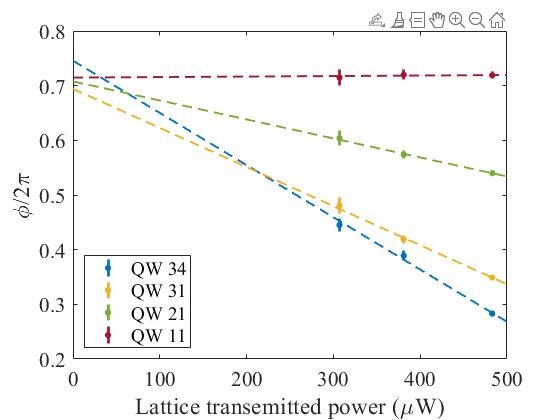


legend(lg,'Location','southwest');

set(gca,'FontName','times new roman',...
    'FontSize',16);
xlabel('Lattice transemitted power (\muW)');
ylabel('\phi/2\pi');

xlim([0 xmax]);
box on;

set(f1,'Visible','on');


f10 = figure; hold on;
for k = 1:length(y10(:,1));
    e1 = errorbar(x10,y10(k,:),err10(k,:),'.',...
        'CapSize',0,'LineWidth',2,'MarkerSize',18);
    [xData, yData] = prepareCurveData(x10,y10(k,:));
    ft = fittype( 'a*x+b', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.weight = w10(k,:);

    [fitresult10, gof] = fit(xData, yData, ft, opts);
    slope10(k) = fitresult10.a;
    phi10(k) = fitresult10.b;
    plot([0 xmax],[phi10(k) phi10(k)+slope10(k)*xmax],...
        '--','LineWidth',1.4,'Color',e1.Color);

    lg{2*k-1} = ['QW ',num2str(QW10(k))];
    lg{2*k} = '';
end


legend(lg,'Location','northwest');

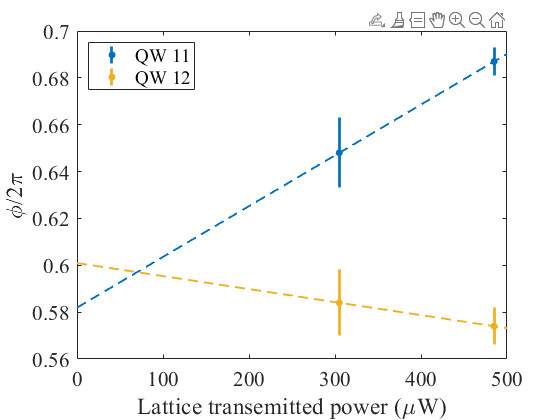


set(gca,'FontName','times new roman',...
    'FontSize',16);
xlabel('Lattice transemitted power (\muW)');
ylabel('\phi/2\pi');

xlim([0 xmax]);
box on;

set(f10,'Visible','on');

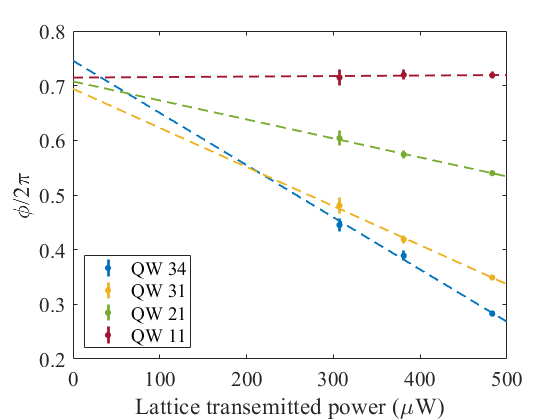


savefig(f1,[maindir,'vector1s.fig']);
saveas(f1,[maindir,'vector1s.png']);

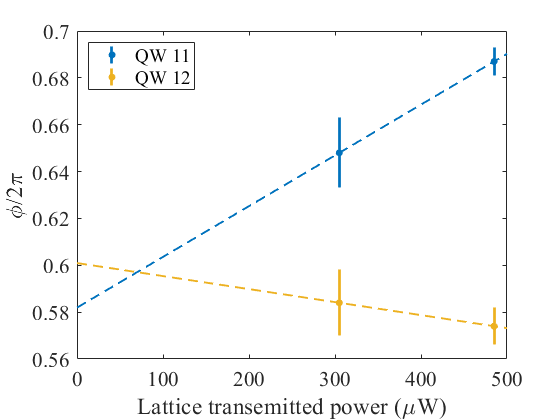

savefig(f10,[maindir,'vector10s.fig']);
saveas(f10,[maindir,'vector10s.png']);

save([maindir,'vector_fit.mat']);